%ER_7.0 calculations and outputs

%Aero related
drag_coeff     = 0.584;
front_area     = 0.7590;

%VD related
CG_height              = 310;
front_axle             = 800;
rear_axle              = 775;
roll_resist            = 0.02;
tire_b                 = 10;
tire_c                 = 1.9;
tire_d                 = 1 ;
tire_e                 = 0.97;
tire_dia               = 18;
tire_inertia           = 0.001;
vehicle_mass           = 220;
rider_mass             = 60;

%Powertrain related
gear_ratio             = 2.267;

%to load drivecycle
%load Drivecycle.mat

%To run the simulink file
sim('ER_7.slx')

%To Extract values from the simulation
% Speed = Speedscope.signals.values;
% Torque = Torquescope.signals.values;
% InstantaneousPower = Instantaneouspower.signals.values;
Time = tout;

%Max speed, torque and Time of simulation
% Ms = max(Speed);
% Mt = max(Torque);
% Instantaneouspower.signals.values
TotalPower_used = sum(Instantaneouspower.signals.values) 

TotalPower_used = 3.1262e+04

Simul_time = max(Time)

Simul_time = 105

% for i = 1 : 1 : 2
%     soc = Instantaneouspower.signals.values
% end

%plotting values

[Ms, indexMax] = max(Speedscope.signals.values)

Ms = 67.1275

indexMax = 521

Timax = Speedscope.time(indexMax)

Timax = 20.5028

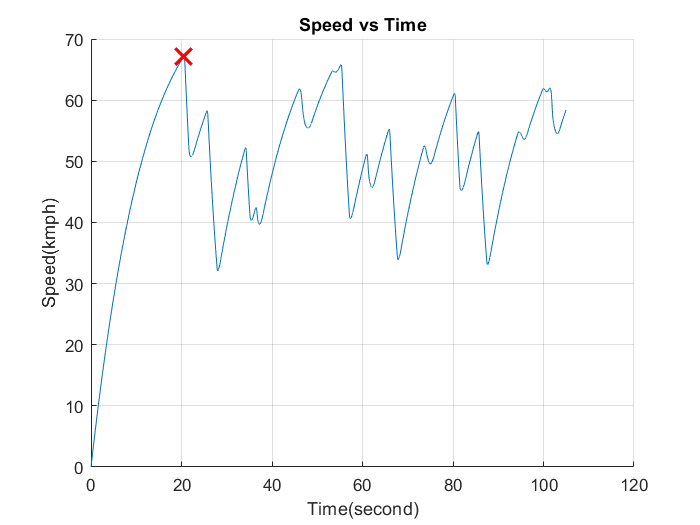


figure 
hold on
plot(Speedscope.time,Speedscope.signals.values)
plot(Timax,Ms,'rx',"LineWidth",2,'MarkerSize',14)
xlabel('Time(second)')
ylabel('Speed(kmph)')
grid on
title('Speed vs Time')

 
[Mt, indexMax] = max(Torquescope.signals.values)

Mt = 129.2325

indexMax = 49

Timax = Torquescope.time(indexMax)

Timax = 0.0085

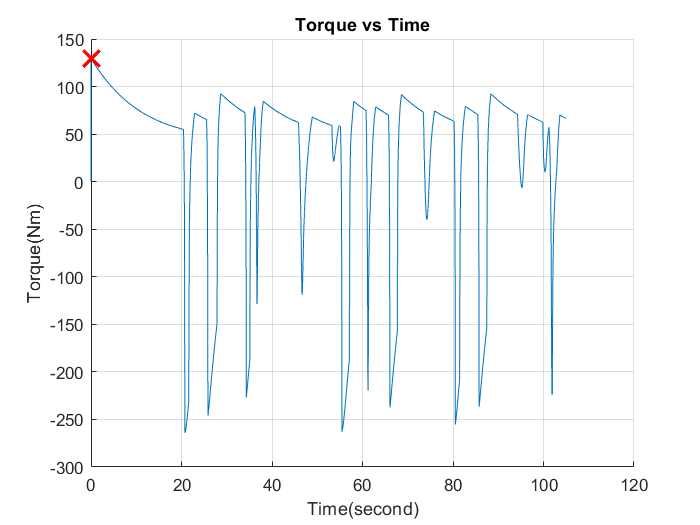


figure
hold on
plot(Torquescope.time,Torquescope.signals.values)
plot(Timax,Mt,'rx',"LineWidth",2,'MarkerSize',14)
xlabel('Time(second)')
ylabel('Torque(Nm)')
grid on
title('Torque vs Time')

 
[Mt , indexMax] = max(Torquescope.signals.values)

Mt = 129.2325

indexMax = 49

Smax = Speedscope.signals.values(indexMax)

Smax = 0.0500

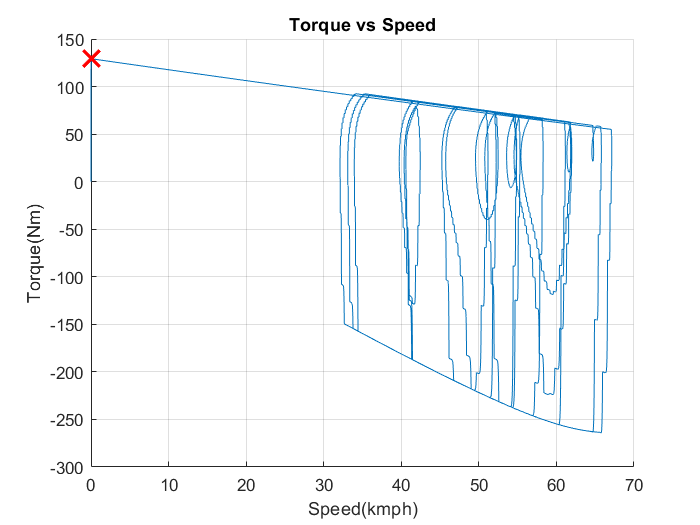

 
figure
hold on
plot(Speedscope.signals.values,Torquescope.signals.values)
plot(Smax ,Mt ,'rx',"LineWidth",2,'MarkerSize',14)
xlabel('Speed(kmph)')
ylabel('Torque(Nm)')
grid on
title('Torque vs Speed')

 
% disp('Check Discrete PID controller Documentary')
disp('Import drive cycle from the OptimumLap and feed that into Simulink Drivecycle block') 

Import drive cycle from the OptimumLap and feed that into Simulink Drivecycle block
